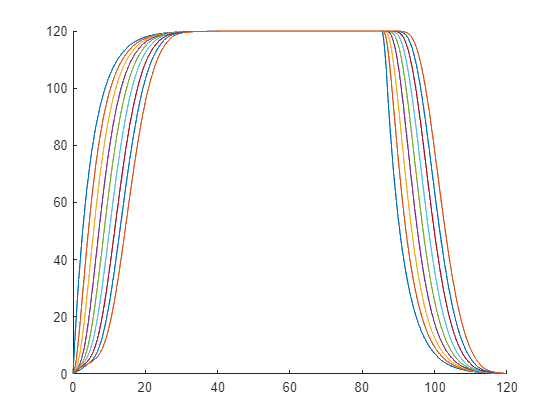

% Constants.
tau = 5;
v_0 = 120; 
T = 1.4;
s_0 = 3;
gamma = 0.6;
t_step = 0.1;
numCars = 9; 
iterations = 1200;

% Initial conditions and storing data.
time = t_step*[0:iterations-1];
posMatrix = zeros(iterations,numCars);
velMatrix = zeros(iterations,numCars);
accMatrix = zeros(iterations,numCars);
gapMatrix = zeros(iterations,numCars);
lengthMatrix = zeros(numCars,1);

dummyVel = 120;

% Inital Conditions
posMatrix(1,:) = [200 180 160 140 120 100 80 60 40];
velMatrix(1,:) = [0 0 0 0 0 0 0 0 0];
lengthMatrix(1) = 9;
lengthMatrix(2) = 4;
lengthMatrix(3) = 6;
lengthMatrix(4) = 6;
lengthMatrix(5) = 5;
lengthMatrix(6) = 10;
lengthMatrix(7) = 13;
lengthMatrix(8) = 5;
lengthMatrix(9) = 6;
gapMatrix(1,1) = gap(10000,0,posMatrix(1,1));
gapMatrix(1,2) = 20;
gapMatrix(1,3) = 20;
gapMatrix(1,4) = 20;
gapMatrix(1,5) = 20;
gapMatrix(1,6) = 20;
gapMatrix(1,7) = 20;
gapMatrix(1,8) = 20;
gapMatrix(1,9) = 20;

% Simulation 
for i=1:iterations-1
for j=1:numCars 
    if j == 1
        accMatrix(i,j) = acc(gapMatrix(i,j),velMatrix(i,j),velMatrix(i,j),tau,gamma,v_0,T,s_0);
        velMatrix(i+1,j) = vel(gapMatrix(i,j),velMatrix(i,j),velMatrix(i,j),t_step,tau,gamma,v_0,T,s_0);
        posMatrix(i+1,j) = pos(velMatrix(i,j),posMatrix(i,j),velMatrix(i,j),t_step);
        gapMatrix(i+1,j) = gap(10000,0,posMatrix(i+1,j));
    else 
        accMatrix(i,j) = acc(gapMatrix(i,j),velMatrix(i,j),velMatrix(i,j-1),tau,gamma,v_0,T,s_0);
        velMatrix(i+1,j) = vel(gapMatrix(i,j),velMatrix(i,j),velMatrix(i,j-1),t_step,tau,gamma,v_0,T,s_0);
        posMatrix(i+1,j) = pos(velMatrix(i,j),posMatrix(i,j),velMatrix(i+1,j),t_step);
        gapMatrix(i+1,j) = gap(posMatrix(i+1,j-1),lengthMatrix(j-1),posMatrix(i+1,j));
    end 
end 
end 
hold on
plot(time,velMatrix(:,1))
plot(time,velMatrix(:,2))
plot(time,velMatrix(:,3))
plot(time,velMatrix(:,4))
plot(time,velMatrix(:,5))
plot(time,velMatrix(:,6))
plot(time,velMatrix(:,7))
plot(time,velMatrix(:,8))
plot(time,velMatrix(:,9))

hold off

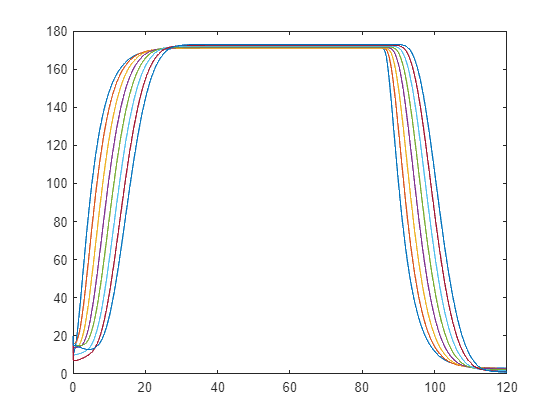

plot(time,gapMatrix(:,2))
hold on
plot(time,gapMatrix(:,3))
plot(time,gapMatrix(:,4))
plot(time,gapMatrix(:,5))
plot(time,gapMatrix(:,6))
plot(time,gapMatrix(:,7))
plot(time,gapMatrix(:,8))
plot(time,gapMatrix(:,9))

hold off

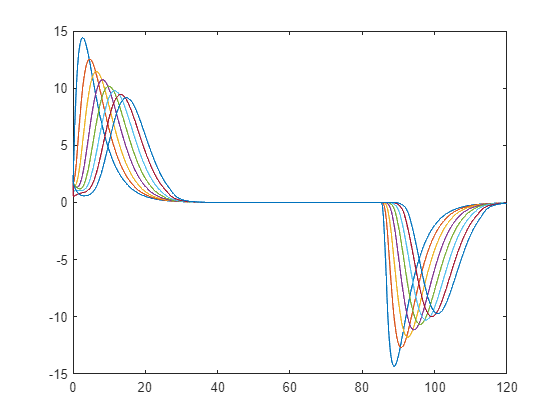

plot(time,accMatrix(:,2))
hold on
plot(time,accMatrix(:,3))
plot(time,accMatrix(:,4))
plot(time,accMatrix(:,5))
plot(time,accMatrix(:,6))
plot(time,accMatrix(:,7))
plot(time,accMatrix(:,8))
plot(time,accMatrix(:,9))

Functions

function [v_opt] = v_opt(s,v_0,T,s_0)  % s is the gap between the cars 
v_opt = max(0,min(v_0,(s-s_0)/(T)));
end

function [a] = acc(s,v_a,v_l,tau,gamma,v_0,T,s_0)
a = ((v_opt(s,v_0,T,s_0) - v_a)/tau) - gamma*(v_a - v_l);
end

function [vel] = vel(s,v_a,v_l,t_step,tau,gamma,v_0,T,s_0)
vel = v_a + acc(s,v_a,v_l,tau,gamma,v_0,T,s_0) * t_step; 
end

function [pos] = pos(v_a,x_a,v_step,t_step)
pos = x_a + ((v_a + v_step)/2)*t_step; 
end

function [gap] = gap(x_l,l_l,x_a)
gap = x_l - l_l - x_a;
end